%% Demo: Soft-saturated Lorenz--96 derivative-noise robustness
% Targeted prior-strength/noise robustness ablation for the PhDN manuscript.
%
% This demo reuses the K=10, F=8, kappa=1 soft-saturated Lorenz--96 system,
% the G1/G2/G3 prior definitions, and the PhDN/MLP hyperparameters of the main
% Lorenz--96 identification case.  Within this fixed robustness protocol only
% the derivative-label noise amplitude is varied. Training and validation
% derivatives receive per-coordinate relative Gaussian noise, while the held-
% out ID-test derivatives remain clean. OOD and dynamic rollout are disabled.
%
% Main manuscript robustness run: Ntrain=1000; rho is set by NoiseLevels below; 3 independent rounds.
% G1/G2/G3 use the finalized general two-restart adaptive-rescue policy.
% Reported methods: PhDN-G1/G2/G3, their collected Stage-0 SR ablations, MLP.

clear; clc;
rng(1);

casemode = 'general';
LorenzDimension = 10;
SaturationKappa = 1;
LorenzForcing = 8;
caseToRun = sprintf('SS_L96_K%d',LorenzDimension);
TrainingSampleList = 1000;
NoiseLevels = [0,0.001,0.005,0.01]; % Set the complete noise sweep here.
NValidationSamples = 500;
NIDTestSamples = 1000;
NumRounds = 3;
% Keep the same simple round-seed convention as the main Lorenz case.
RoundRandomStateStride = 1;
BaseNoiseSeed = 22001;

% Fixed scrambled-Sobol state samples for all rho and all rounds. Only the
% derivative-noise realization and optimization seed change across rounds.
SamplingMethod = 'scrambled_sobol';
SobolScrambleMethod = 'MatousekAffineOwen';
SobolSkip = 1024;
MaxTrainingSamples = TrainingSampleList;
BaseTrainPoolSeed = 7301;
BaseValidationPoolSeed = 7401;
BaseTestPoolSeed = 7501;
BaseOODPoolSeed = 8501;

projectRoot = pwd;
if ~exist(fullfile(projectRoot,'core'),'dir') || ~exist(fullfile(projectRoot,'tasks'),'dir')
    try
        activeFile = matlab.desktop.editor.getActiveFilename;
        projectRoot = fileparts(activeFile);
    catch
        error('Cannot locate the project root. Set the current folder to the framework root.');
    end
end
addpath(genpath(projectRoot));
addpath(fullfile(projectRoot,'system_identification'),'-begin');
rehash;

% Reuse the SAME output tree. Legacy integer-percent folders are preserved,
% while fractional-percent cases use noncolliding basis-point keys.
NoiseStorageKeys = arrayfun(@(rho) soft_saturated_lorenz96_noise_key(rho), ...
    NoiseLevels,'UniformOutput',false);
assert(numel(unique(NoiseStorageKeys))==numel(NoiseStorageKeys), ...
    'NoiseLevels produce colliding storage keys.');

caseDefinitionTask = task_soft_saturated_lorenz96( ...
    caseToRun,casemode,LorenzForcing,SaturationKappa);
verify_soft_saturated_lorenz96_case_setup(caseDefinitionTask);

SoftSaturatedLorenz96 mapping verified: x1,...,x10 are cyclic Lorenz--96 states
K=10 | F=8 | kappa=1 | equilibrium max |RHS|=0.000e+00
Alternating joint-OOD static and rollout designs verified.


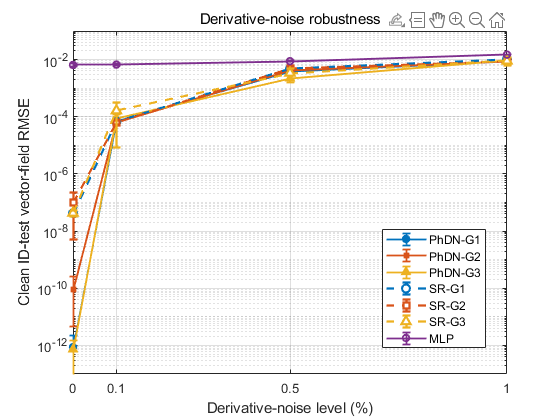


Fast compact replay summary (mean/std):


        method        noiseLevel    noisePercent    nRuns    idRMSEMean    idRMSEStd 
    ______________    __________    ____________    _____    __________    __________

    "PhDN-G1"               0             0           3      8.7253e-13    1.4402e-12
    "PhDN-G1"           0.001           0.1           3      6.6953e-05    2.9423e-06
    "PhDN-G1"           0.005           0.5           3       0.0038711    0.00016639
    "PhDN-G1"            0.01             1           3       0.0086426     0.0015707
    "PhDN-G2"               0             0           3      9.2893e-11    1.5868e-10
    "PhDN-G2"           0.001           0.1           3      6.3985e-05     1.003e-05
    "PhDN-G2"           0.005           0.5           3       0.0042018    0.00019881
    "PhDN-G2"            0.01             1           3       0.0085189    0.00039667
    "PhDN-G3"               0             0           3      7.3147e-13    7.6495e-13
    "PhDN-G3"           0.001           0.1          


Fast Lorenz--96 robustness replay finished in 2.660 s.


Large aggregate allResults was never loaded or rewritten.


Compact source  : D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SoftSaturatedLorenz96_K10_F8_kappa1_NoiseRobustness\summary\l96_noise_rows.mat


Detailed CSV    : D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SoftSaturatedLorenz96_K10_F8_kappa1_NoiseRobustness\summary\lorenz96_noise_robustness_all_runs.csv


Mean/std CSV    : D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SoftSaturatedLorenz96_K10_F8_kappa1_NoiseRobustness\summary\lorenz96_noise_robustness_mean_std.csv


Paper PDF       : D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SoftSaturatedLorenz96_K10_F8_kappa1_NoiseRobustness\summary\lorenz96_noise_robustness.pdf



OutputCaseRoot = fullfile(projectRoot,'outputs', ...
    [caseDefinitionTask.name '_NoiseRobustness']);
OutputSummaryDir = fullfile(OutputCaseRoot,'summary');
if exist(OutputSummaryDir,'dir') ~= 7; mkdir(OutputSummaryDir); end
ResultsFile = fullfile(OutputSummaryDir, ...
    'soft_saturated_lorenz96_noise_robustness_results.mat');
CompactRowsFile = fullfile(OutputSummaryDir,'l96_noise_rows.mat'); % short Windows-safe cache path

IncludeStage0SRAblationsInComparison = true;
RegeneratePaperFiguresOnly = false;
PaperFigureVisible = true;
PaperFigureExportPDF = true;
RMSEFigureYLimits = []; % []=automatic; optionally set [ymin ymax].
if RegeneratePaperFiguresOnly
    if exist(CompactRowsFile,'file') ~= 2
        error('Compact row cache not found: %s',CompactRowsFile);
    end
    replayPayload = load(CompactRowsFile,'noiseRows');
    replayMethods = {'PhDN-G1','PhDN-G2','PhDN-G3','MLP'};
    if IncludeStage0SRAblationsInComparison
        replayMethods = {'PhDN-G1','PhDN-G2','PhDN-G3', ...
            'Stage0-SR-G1','Stage0-SR-G2','Stage0-SR-G3','MLP'};
    end
    replayRows = filter_soft_saturated_lorenz96_noise_rows( ...
        replayPayload.noiseRows,NoiseLevels,NumRounds,replayMethods);
    [figNoise,noiseFigureData,noiseSummaryTable] = ...
        plot_soft_saturated_lorenz96_noise_robustness( ...
            replayRows,'Visible',PaperFigureVisible,'YLimits',RMSEFigureYLimits);
    writetable(noiseSummaryTable,fullfile(OutputSummaryDir,'lorenz96_noise_robustness_mean_std.csv'));
    save(fullfile(OutputSummaryDir,'lorenz96_noise_robustness_figure_data.mat'), ...
        'noiseFigureData','noiseSummaryTable','-v7');
    savefig(figNoise,fullfile(OutputSummaryDir,'lorenz96_noise_robustness.fig'));
    if PaperFigureExportPDF
        exportgraphics(figNoise,fullfile(OutputSummaryDir,'lorenz96_noise_robustness.pdf'), ...
            'ContentType','vector');
    end
    fprintf('\nLorenz--96 low-noise robustness figure regenerated from compact rows:\n%s\n', ...
        CompactRowsFile);
    return;
end
CaseSimulationWallTimer = tic;

%% Stage 0: trivial-output bypass plus native multi-output PySR
% A generic flat SINDy dictionary is accepted only near machine precision.
% All unresolved outputs are searched by PySR with the fine-grained operators
% needed to assemble the soft-saturation law, but without the completed target
% composite feature.
Stage0SingleLayerBypassEnable = true;
Stage0SingleLayerBypassThreshold = 1e-24;

Stage0BasePolyOrder = 2;
Stage0BaseUnaryOperators = {'sqrt'};
Stage0BaseIncludeUnaryOnMonomials = false;
Stage0BaseIncludeOperatorCrossTerms = false;
Stage0BaseIncludeSinCosPair = false;
Stage0BaseMaxLibraryTerms = Inf;
Stage0STLSQThresholdList = [0,1e-8,1e-7,1e-6,1e-5,1e-4,1e-3];
Stage0STLSQMaxIter = 10;
Stage0RidgeLambda = 0;
Stage0WorstOutputWeight = 0.10;

Stage0PythonExe = 'C:\Users\hhy\miniconda3\envs\pysr_sr\python.exe';
Stage0PySRPaperRoot = fullfile(projectRoot,'baselines','pysr_paper_main');
Stage0WorkRoot = fullfile(projectRoot,'tmp', ...
    'stage0_pysr_soft_saturated_l96_noise_robustness_runs');
Stage0GrammarCasemode = casemode;

Stage0UseCustomSRGrammar = true;
Stage0SRBinaryOperators = {'+','-','*','/'};
Stage0SRUnaryOperators = {'square','sqrt'};
Stage0TypedPhysicalPriorEnable = false;
Stage0TypedPhysicalPriorMode = '';
Stage0SRTrigAllowedVariables = {};
Stage0SRForbidStateDependentDivision = false;
Stage0SROperatorComplexities = struct();
Stage0SRStrictTrigAtomsOnly = false;
Stage0SRForbidNestedTrig = true;
Stage0SRForbidNestedSquare = true;
Stage0SRForbidNestedSqrt = true;

% Optional Stage-0 SR initial-guess port. As in the main Lorenz case,
% the actual guess expressions are kept explicit and manual.
% This robustness demo uses the original uncalibrated structural priors:
% no training-sample LS coefficient fitting is applied to the guess expressions.
%
% Prior hierarchy:
%   G1: no Stage-0 initial guess.
%   G2: ideal unsaturated cyclic transport+damping,
%         x_{i-1}(x_{i+1}-x_{i-2}) - x_i;
%       forcing and smooth saturation are unknown.
%   G3: the same ideal unsaturated topology plus the prior-known forcing F=8;
%       only smooth saturation is unknown.
%
% The SAME manual raw G2/G3 expressions are held fixed for every noise level
% and every robustness round, so the robustness experiment changes derivative
% noise only.
%
% Official PySR multi-output behavior remains unchanged: these ten manual
% expressions form one shared guess library for all unresolved outputs; no
% guess tree is hard-assigned to a specific output.
Stage0SRMinimumPySRVersion = '2.0.0a2';
Stage0SRRequirePySR2 = true;
Stage0SRInitialGuessFraction = 0.10;

assert(LorenzDimension==10 && abs(LorenzForcing-8)<1e-12 && ...
    abs(SaturationKappa-1)<1e-12, ...
    ['The manually entered Lorenz--96 prior block below is written for ', ...
     'K=10, F=8, kappa=1. Update the manual cyclic expressions if these ', ...
     'case parameters change.']);

% G1: no initial guess.
Stage0SRInitialGuesses_G1 = {};

% G2: ideal unsaturated cyclic transport+damping; forcing is not supplied.
Stage0SRInitialGuesses_G2 = { ...
    'x10*(x2-x9)-x1', ...
    'x1*(x3-x10)-x2', ...
    'x2*(x4-x1)-x3', ...
    'x3*(x5-x2)-x4', ...
    'x4*(x6-x3)-x5', ...
    'x5*(x7-x4)-x6', ...
    'x6*(x8-x5)-x7', ...
    'x7*(x9-x6)-x8', ...
    'x8*(x10-x7)-x9', ...
    'x9*(x1-x8)-x10'};

% G3: same unsaturated topology with the prior-known forcing F=8.
Stage0SRInitialGuesses_G3 = { ...
    'x10*(x2-x9)-x1+8', ...
    'x1*(x3-x10)-x2+8', ...
    'x2*(x4-x1)-x3+8', ...
    'x3*(x5-x2)-x4+8', ...
    'x4*(x6-x3)-x5+8', ...
    'x5*(x7-x4)-x6+8', ...
    'x6*(x8-x5)-x7+8', ...
    'x7*(x9-x6)-x8+8', ...
    'x8*(x10-x7)-x9+8', ...
    'x9*(x1-x8)-x10+8'};

assert(numel(Stage0SRInitialGuesses_G2)==LorenzDimension && ...
       all(~cellfun(@isempty,Stage0SRInitialGuesses_G2)), ...
    'G2 must contain ten manually entered raw cyclic expressions.');
assert(numel(Stage0SRInitialGuesses_G3)==LorenzDimension && ...
       all(~cellfun(@isempty,Stage0SRInitialGuesses_G3)), ...
    'G3 must contain ten manually entered raw cyclic expressions.');

% Keep the metadata helper for common fields, then explicitly record the exact
% raw manual prior definitions used in this robustness experiment.
[~,Stage0PriorInfo_G1] = make_lorenz96_unsaturated_initial_guesses( ...
    LorenzDimension,LorenzForcing,'G1');
[~,Stage0PriorInfo_G2] = make_lorenz96_unsaturated_initial_guesses( ...
    LorenzDimension,LorenzForcing,'G2');
[~,Stage0PriorInfo_G3] = make_lorenz96_unsaturated_initial_guesses( ...
    LorenzDimension,LorenzForcing,'G3');

Stage0PriorInfo_G2.name = 'unsaturated_transport_and_damping_unknown_forcing';
Stage0PriorInfo_G2.description = [ ...
    'Ideal unsaturated cyclic transport and -x_i damping; the forcing ', ...
    'and smooth saturation are unknown. No guess-coefficient fitting is used.'];
Stage0PriorInfo_G2.includesTransport = true;
Stage0PriorInfo_G2.includesDamping = true;
Stage0PriorInfo_G2.includesForcing = false;
Stage0PriorInfo_G2.priorForcing = NaN;
Stage0PriorInfo_G2.coefficientCalibration = 'none';
Stage0PriorInfo_G2.outerCoefficientSource = 'manual_theory_unit_coefficients';
Stage0PriorInfo_G2.manualExpressions = Stage0SRInitialGuesses_G2;

Stage0PriorInfo_G3.name = 'full_unsaturated_lorenz96';
Stage0PriorInfo_G3.description = [ ...
    'Complete ideal unsaturated Lorenz--96 law with the prior-known true ', ...
    'forcing F; only smooth saturation is unknown. No guess-coefficient fitting is used.'];
Stage0PriorInfo_G3.includesTransport = true;
Stage0PriorInfo_G3.includesDamping = true;
Stage0PriorInfo_G3.includesForcing = true;
Stage0PriorInfo_G3.priorForcing = LorenzForcing;
Stage0PriorInfo_G3.coefficientCalibration = 'none';
Stage0PriorInfo_G3.forcingInitialization = 'prior-known F=8';
Stage0PriorInfo_G3.outerCoefficientSource = 'manual_theory_unit_coefficients_plus_known_forcing';
Stage0PriorInfo_G3.manualExpressions = Stage0SRInitialGuesses_G3;

Stage0SRInitialGuessFraction_G1 = 0;
Stage0SRInitialGuessFraction_G2 = Stage0SRInitialGuessFraction;
Stage0SRInitialGuessFraction_G3 = Stage0SRInitialGuessFraction;
assert(isempty(Stage0SRInitialGuesses_G1), ...
    'G1 must contain no Stage-0 initial guesses.');

Stage0PriorAblation = struct();
Stage0PriorAblation.G1 = Stage0PriorInfo_G1;
Stage0PriorAblation.G2 = Stage0PriorInfo_G2;
Stage0PriorAblation.G3 = Stage0PriorInfo_G3;
Stage0PriorAblation.G1.initialGuesses = Stage0SRInitialGuesses_G1;
Stage0PriorAblation.G2.initialGuesses = Stage0SRInitialGuesses_G2;
Stage0PriorAblation.G3.initialGuesses = Stage0SRInitialGuesses_G3;
Stage0PriorAblation.G1.initialGuessFraction = Stage0SRInitialGuessFraction_G1;
Stage0PriorAblation.G2.initialGuessFraction = Stage0SRInitialGuessFraction_G2;
Stage0PriorAblation.G3.initialGuessFraction = Stage0SRInitialGuessFraction_G3;
caseDefinitionTask.prior.stage0PriorAblation = Stage0PriorAblation;

Stage0PopulationSize = 100;
Stage0InnerNumRestarts = 3;
Stage0InnerNIterations = 700;
Stage0InnerPopulations = 4*LorenzDimension; % current robustness setting: four protected populations per output
Stage0PopulationBudgetMode = 'fixed_total';
Stage0InnerRandomStateStride = 100;

% General output-self-referenced Stage-0 targeted rescue.
% Trigger A: best normalized validation MSE remains above the soft threshold
% AND the ordinary restarts are unstable for that same output.
% Trigger B: the ordinary restarts are relatively consistent, but even their
% best normalized validation MSE remains above the hard threshold.
% Once A or B triggers, run up to two official single-output PySR rescue
% restarts for that output. Stop early only when the running best reaches the
% soft threshold. Rescue-only guess injection is reduced to 0.05 to preserve
% prior guidance while increasing exploration. Known derivative-label noise
% raises the soft/hard thresholds above 4x the expected validation-noise MSE floor.
Stage0AdaptiveRescueEnable = true;
Stage0AdaptiveRescueSoftNormalizedMSE = 1e-6;
Stage0AdaptiveRescueHardNormalizedMSE = 1e-4;
Stage0AdaptiveRescueInstabilityFactor = 5;
Stage0AdaptiveRescueContinueImprovementRatio = 0.5; % legacy compatibility; fixed-two policy ignores this
Stage0AdaptiveRescueGuessFraction = 0.05;
Stage0AdaptiveRescueUseKnownNoiseFloor = true;
Stage0AdaptiveRescueNoiseFloorMultiplier = 4;
Stage0AdaptiveRescueMaxRestartsPerOutput = 2;
Stage0AdaptiveRescuePopulationMultiplier = 1.5;
Stage0AdaptiveRescueMinPopulations = 8;
Stage0AdaptiveRescueMaxPopulations = 20;
Stage0AdaptiveRescueExplicitPopulations = []; % [] -> adaptive population rule
Stage0AdaptiveRescueNIterations = Stage0InnerNIterations;
Stage0AdaptiveRescueMaxOutputs = 3;
Stage0AdaptiveRescueUseOutputSpecificInitialGuess = true;
Stage0AdaptiveRescueSeedOffset = 10000;
Stage0AdaptiveRescueOutputSeedStride = 1000;
Stage0AdaptiveRescueRestartSeedStride = 100;
Stage0TournamentSelectionN = 8;
Stage0TournamentSelectionP = 0.85;
Stage0CrossoverProbability = [];
Stage0WeightAddNode = [];
Stage0WeightInsertNode = [];
Stage0WeightDeleteNode = [];
Stage0WeightDoNothing = [];
Stage0WeightMutateConstant = [];
Stage0WeightMutateOperator = [];
Stage0WeightMutateFeature = [];
Stage0WeightSwapOperands = [];
Stage0WeightRotateTree = [];
Stage0WeightRandomize = [];
Stage0WeightSimplify = [];
Stage0WeightOptimize = [];
Stage0OptimizeProbability = [];
Stage0ShouldSimplify = [];
Stage0MaxDepth = 12;
Stage0MaxSize = 40;
Stage0Parsimony = 1e-6;
Stage0ModelSelection = 'best';
Stage0RandomState = 1;
Stage0Deterministic = false;
Stage0Parallelism = 'multithreading';
Stage0Batching = false;
Stage0BatchSizeList = TrainingSampleList; % fixed N=1000 robustness case
assert(numel(Stage0BatchSizeList)==numel(TrainingSampleList), ...
    'Stage0BatchSizeList must match TrainingSampleList.');
assert(all(Stage0BatchSizeList>=1 & Stage0BatchSizeList<=TrainingSampleList), ...
    'Every Stage-0 batch size must be positive and no larger than Ntrain.');
Stage0StrictDeterministicTestMode = false;
Stage0RepeatabilityPredictionTolerance = 1e-12;
Stage0MachinePrecisionEarlyStopEnable = true;
Stage0MachinePrecisionEarlyStopAbsMSE = 1e-14;
Stage0MachinePrecisionEarlyStopRelMSE = 1e-14;
Stage0MachinePrecisionEarlyStopCheckInterval = 50;
Stage0MachinePrecisionEarlyStopMinIterations = 50;
Stage0MachinePrecisionEarlyStopAcrossRestarts = true;
Stage0Verbosity = 1;
Stage0Progress = false;
Stage0TopKExpressionsToReport = 10;
Stage0DisplayCandidateRankings = true;
Stage0CandidateRankingTopK = 10;
Stage0SemanticDedupTolerance = 1e-8;
Stage0StructureScoreEnable = true;
Stage0StructureValidationMultiplier = 4.0;
Stage0StructureValidationWeight = 0.30;
Stage0StructureMachineErrorAbsMSEFloor = 1e-14;
Stage0StructureMachineErrorRelMSEFloor = 1e-14;
Stage0StructureFrontierMaxAbs = 20;
Stage0StructureNeighborhoodMaxDistance = 0.55;
Stage0StructureNeighborhoodMinDistance = 0.10;
Stage0StructureNeighborhoodComplexityWindow = 8;

%% Stage 1 and Stage 2
% Unlike the generator case, the degree-two polynomial block is replaced by
% K fixed neural ridges. The constant and all first-order branch coordinates
% are retained, so only the nonlinear augmentation family is changed.
Stage1EnableAugmentation = true;
Stage1AugmentationMode = 'fixed_neural_ridge';
Stage1AugmentationNeuralCount = LorenzDimension;
Stage1AugmentationNeuralActivation = 'tanh';
Stage1AugmentationNeuralQuantiles = [0.20,0.40,0.60,0.80]; % 4 locations x 3 scales = 12 shapes per 1-D branch
Stage1AugmentationNeuralScales = [0.5,1,2];
Stage1AugmentationNeuralPoolRatio = 3;
Stage1AugmentationNeuralSeed = 1701;
Stage1AugmentationNeuralStdFloor = 1e-10;
Stage1AugmentationNeuralVarianceThreshold = 1e-8;
Stage1AugmentationNeuralCorrelationThreshold = 0.995;
Stage1AugmentationNeuralEnsureFullDirectionalSpan = true;
Stage1AugmentationNeuralIncludeLinearTerms = true;
Stage1ForceStage0SeedOnly = true;
Stage1ExpandBoundsToIncludeStage0Seed = true;
Stage1Stage0SeedBoundMargin = 1e-6;
Stage1RequireExactStage0Reproduction = true;
Stage1Stage0ReproductionRelTolerance = 1e-6;
Stage1Stage0ReproductionAbsTolerance = 1e-10;

Stage2Enable = true;
% Reporting only: inspect whether zero-initialized neural/linear augmentation
% coefficients move, are validation-accepted, and survive pruning.
Stage2AugmentationDiagnosticsEnable = true;
FinalLSQMaxIter = 500;
FinalLSQMaxFunEvals = 5e4;
FinalLSQMaxRelValIncrease = 1e-10;
PostBPPruneEnable = true;
PostBPPruneNumIterations = 1;
PostBPPruneAbsThreshold = 1e-4;
PostBPPruneRelThreshold = 0;
PostBPPruneMaxRelValIncrease = 1e-4;


%% Methods and output controls
InitializationMode = 'skip';
EnableOOD = false;
DisplayDictionary = true;
PrintFinalXiMatrices = false;
FinalXiPrintPrecision = 4;
FinalXiPrintOnlyActive = false;

% The legacy sample-efficiency persistence path is deliberately disabled in
% this dedicated rho-keyed experiment. SaveNoiseResults controls its checkpoint.
SaveResults = false;
SaveNoiseResults = false;

% Method run switches. Every enabled method is evaluated at every noise level in NoiseLevels.
RunPhDNMainModel_G1 = false;
RunPhDNMainModel_G2 = false;
RunPhDNMainModel_G3 = false;
RunMLPBaseline = false;
SkipExistingScheduledCheckpoints = false; % crash-safe resume for the long sweep

RecordedBaselineSourceRoot = OutputCaseRoot;
RecordedBaselineReplayStrict = false;
RecordedReportCompactMode = true;
displayRecordReport_PhDN_G1 = true;
displayRecordReport_PhDN_G2 = true;
displayRecordReport_PhDN_G3 = true;
% Independent Stage-0 SR replay/report controls.
displayRecordReport_SR1 = true;
displayRecordReport_SR2 = true;
displayRecordReport_SR3 = true;
displayRecordReport_MLP = true;

% Fast replay path. Normal replay uses a compact row index only and never loads
% aggregate allResults. If the compact rows are absent/stale (for example after
% an interrupted long sweep), they are rebuilt ONCE from the dedicated
% round/rho/method_results checkpoints, one checkpoint at a time, then cached in
% a small sidecar MAT for future near-instant replay.
FastAggregateReplay = true;
FastAggregateReplayPrintSummaryTable = true;
FastAggregateReplayRequireCompletePhDN = true;
FastAggregateReplayAutoRebuildCompactRows = true;
FastAggregateReplayIncludeAvailableMLP = true; % missing noisy MLP is allowed
% Keep legacy high-noise folders/checkpoints in place. Do not reload/rewrite the
% historically huge aggregate allResults tree during staged completion.
PersistLegacyAggregateAllResults = false;

% MLP settings are identical to the main Lorenz--96 case.
MLPSeed = 1;
MLPProtocol = 'kan_feynman_sweep';
MLPWidth = 64;
MLPDepthList = 2:6;
MLPActivationList = {'tanh','relu','silu'};
MLPOptimizer = 'LBFGS';
MLPSteps = 500;
MLPLearningRate = 1.0;
MLPDtype = 'float64';
MLPDevice = 'cpu';
MLPTorchNumThreads = 0;
MLPNormalizeInputs = true;
MLPNormalizeOutputs = true;
MLPPythonExe = Stage0PythonExe;
MLPPyKANRoot = fullfile(projectRoot,'third_party','pykan');
MLPWorkRoot = fullfile(projectRoot,'tmp','mlp_soft_saturated_lorenz96_noise_runs');
MLPDepthEarlyStop = true;
MLPDepthEarlyStopPatience = 1;
MLPDepthEarlyStopRelativeTolerance = 0.0;
MLPDisplaySweepTable = true;
MLPVerbose = true;

baselineSweep = soft_saturated_lorenz96_baseline_sweep_options( ...
    projectRoot,Stage0PythonExe);
baselineSweep.runMLP = RunMLPBaseline;
baselineSweep.runEQL = false;
baselineSweep.runKAN = false;
baselineSweep.runSINDy = false;
baselineSweep.runNeuralSINDy = false;
baselineSweep.mlp.protocol = MLPProtocol;
baselineSweep.mlp.width = MLPWidth;
baselineSweep.mlp.depthList = MLPDepthList;
baselineSweep.mlp.activationList = MLPActivationList;
baselineSweep.mlp.optimizer = MLPOptimizer;
baselineSweep.mlp.steps = MLPSteps;
baselineSweep.mlp.learningRate = MLPLearningRate;
baselineSweep.mlp.dtype = MLPDtype;
baselineSweep.mlp.device = MLPDevice;
baselineSweep.mlp.torchNumThreads = MLPTorchNumThreads;
baselineSweep.mlp.normalizeInputs = MLPNormalizeInputs;
baselineSweep.mlp.normalizeOutputs = MLPNormalizeOutputs;
baselineSweep.mlp.pythonExe = MLPPythonExe;
baselineSweep.mlp.pykanRoot = MLPPyKANRoot;
baselineSweep.mlp.workRoot = MLPWorkRoot;
baselineSweep.mlp.depthEarlyStop = MLPDepthEarlyStop;
baselineSweep.mlp.depthEarlyStopPatience = MLPDepthEarlyStopPatience;
baselineSweep.mlp.depthEarlyStopRelativeTolerance = MLPDepthEarlyStopRelativeTolerance;
baselineSweep.mlp.displaySweepTable = MLPDisplaySweepTable;
baselineSweep.mlp.verbose = MLPVerbose;


%% Run derivative-noise robustness sweep
RobustnessComparisonMethods = {'PhDN-G1','PhDN-G2','PhDN-G3','MLP'};
if IncludeStage0SRAblationsInComparison
    RobustnessComparisonMethods = { ...
        'PhDN-G1','PhDN-G2','PhDN-G3', ...
        'Stage0-SR-G1','Stage0-SR-G2','Stage0-SR-G3','MLP'};
end

PureRecordedReplay = ~(RunPhDNMainModel_G1 || RunPhDNMainModel_G2 || ...
    RunPhDNMainModel_G3 || RunMLPBaseline);

% FAST compact replay: no aggregate allResults loading and no full-model merge.
% Prefer the compact sidecar. If it is missing/stale, recover it directly from
% the dedicated method checkpoints without using the old aggregate fallback.
if FastAggregateReplay && PureRecordedReplay
    fastReplayTimer = tic;
    storedNoiseRows = struct([]);
    noiseRows = struct([]);
    compactSource = '';

    if exist(CompactRowsFile,'file') == 2
        try
            compactLoaded = load(CompactRowsFile,'noiseRows');
            if isfield(compactLoaded,'noiseRows') && isstruct(compactLoaded.noiseRows) && ...
                    ~isempty(compactLoaded.noiseRows)
                storedNoiseRows = compactLoaded.noiseRows;
                compactSource = CompactRowsFile;
            end
            clear compactLoaded;
        catch ME
            warning(['Ignoring unreadable compact replay cache ' CompactRowsFile ': ' ME.message]);
            storedNoiseRows = struct([]);
            compactSource = '';
        end
    end

    % Cheap legacy source: aggregate noiseRows only. Never load allResults.
    if isempty(storedNoiseRows) && exist(ResultsFile,'file') == 2
        aggregateRowsOnly = load(ResultsFile,'noiseRows');
        if isfield(aggregateRowsOnly,'noiseRows') && isstruct(aggregateRowsOnly.noiseRows) && ...
                ~isempty(aggregateRowsOnly.noiseRows)
            storedNoiseRows = aggregateRowsOnly.noiseRows;
            compactSource = ResultsFile;
        end
        clear aggregateRowsOnly;
    end

    if ~isempty(storedNoiseRows) && isfield(storedNoiseRows,'method')
        keepPrimary = ismember(lower(string({storedNoiseRows.method})), ...
            lower(string(RobustnessComparisonMethods)));
        storedNoiseRows = storedNoiseRows(keepPrimary);
    end

    % Filter to the CURRENT noise grid before checking completeness. An old
    % 0/1/5/10% cache therefore cannot be mistaken for 0/0.1/0.5/1% merely
    % because both contain 12 rows per method.
    noiseRows = filter_soft_saturated_lorenz96_noise_rows( ...
        storedNoiseRows,NoiseLevels,NumRounds,RobustnessComparisonMethods);
    requiredPhDN = {'PhDN-G1','PhDN-G2','PhDN-G3'};
    compactComplete = true;
    if FastAggregateReplayRequireCompletePhDN
        [compactComplete,coverageReport] = validate_soft_saturated_lorenz96_noise_rows( ...
            noiseRows,NoiseLevels,NumRounds,requiredPhDN);
        if ~compactComplete
            for iMiss = 1:numel(coverageReport.missing)
                fprintf('Fast replay compact index missing: %s\n',coverageReport.missing{iMiss});
            end
        end
    end

    if ~compactComplete
        if ~FastAggregateReplayAutoRebuildCompactRows
            error(['Compact robustness rows are incomplete for the current noise grid. Set ', ...
                'FastAggregateReplayAutoRebuildCompactRows=true to rebuild them ', ...
                'from the dedicated method checkpoints.']);
        end

        fprintf(['\nRebuilding CURRENT-grid Lorenz--96 robustness rows directly from ', ...
            'dedicated method checkpoints.\n']);
        fprintf(['Existing 5%%/10%% checkpoint folders remain untouched; the large ', ...
            'aggregate allResults variable will NOT be loaded.\n']);
        [rebuiltCurrentRows,rebuildInfo] = rebuild_soft_saturated_lorenz96_noise_compact_rows( ...
            OutputCaseRoot,NoiseLevels,NumRounds,TrainingSampleList, ...
            'IncludeStage0SRAblations',IncludeStage0SRAblationsInComparison, ...
            'IncludeMLP',FastAggregateReplayIncludeAvailableMLP, ...
            'RequireCompletePhDN',FastAggregateReplayRequireCompletePhDN, ...
            'Verbose',true);
        storedNoiseRows = merge_soft_saturated_lorenz96_noise_rows( ...
            storedNoiseRows,rebuiltCurrentRows);
        save_soft_saturated_lorenz96_noise_compact_rows( ...
            CompactRowsFile,storedNoiseRows,rebuildInfo);
        compactSource = CompactRowsFile;
        noiseRows = filter_soft_saturated_lorenz96_noise_rows( ...
            storedNoiseRows,NoiseLevels,NumRounds,RobustnessComparisonMethods);
        fprintf('Compact replay index cached at:\n%s\n',CompactRowsFile);
    elseif ~strcmp(compactSource,CompactRowsFile)
        % Preserve all known rho rows in the cache; plotting below uses only the
        % current NoiseLevels.
        save_soft_saturated_lorenz96_noise_compact_rows( ...
            CompactRowsFile,storedNoiseRows);
        compactSource = CompactRowsFile;
    end

    if ~isempty(noiseRows)
        methodRank = zeros(1,numel(noiseRows));
        for iRowSort = 1:numel(noiseRows)
            rankCandidate = find(strcmpi(RobustnessComparisonMethods,noiseRows(iRowSort).method),1);
            if isempty(rankCandidate); rankCandidate = numel(RobustnessComparisonMethods)+1; end
            methodRank(iRowSort) = rankCandidate;
        end
        [~,rowOrder] = sortrows([[noiseRows.roundIndex].',[noiseRows.noiseLevel].',methodRank.'],[1 2 3]);
        noiseRows = noiseRows(rowOrder);
    end

    detailedTable = soft_saturated_lorenz96_noise_rows_to_table(noiseRows);
    detailedCsvPath = fullfile(OutputSummaryDir,'lorenz96_noise_robustness_all_runs.csv');
    writetable(detailedTable,detailedCsvPath);
    [figNoise,noiseFigureData,noiseSummaryTable] = ...
        plot_soft_saturated_lorenz96_noise_robustness( ...
            noiseRows,'Visible',PaperFigureVisible,'YLimits',RMSEFigureYLimits);
    summaryCsvPath = fullfile(OutputSummaryDir,'lorenz96_noise_robustness_mean_std.csv');
    writetable(noiseSummaryTable,summaryCsvPath);
    figureDataPath = fullfile(OutputSummaryDir,'lorenz96_noise_robustness_figure_data.mat');
    save(figureDataPath,'noiseFigureData','noiseSummaryTable','-v7.3');
    figPath = fullfile(OutputSummaryDir,'lorenz96_noise_robustness.fig');
    pdfPath = fullfile(OutputSummaryDir,'lorenz96_noise_robustness.pdf');
    savefig(figNoise,figPath);
    if PaperFigureExportPDF
        try
            exportgraphics(figNoise,pdfPath,'ContentType','vector');
        catch
            set(figNoise,'PaperPositionMode','auto');
            print(figNoise,pdfPath,'-dpdf','-painters');
        end
    end

    if FastAggregateReplayPrintSummaryTable
        fprintf('\nFast compact replay summary (mean/std):\n');
        disp(noiseSummaryTable);
    end
    fastReplayWallTime = toc(fastReplayTimer);
    fprintf('\nFast Lorenz--96 robustness replay finished in %.3f s.\n',fastReplayWallTime);
    fprintf('Large aggregate allResults was never loaded or rewritten.\n');
    fprintf('Compact source  : %s\n',compactSource);
    fprintf('Detailed CSV    : %s\n',detailedCsvPath);
    fprintf('Mean/std CSV    : %s\n',summaryCsvPath);
    if PaperFigureExportPDF; fprintf('Paper PDF       : %s\n',pdfPath); end
    return;
end


allResults = struct();
systemIdentificationRows = struct([]);
% Seed the row index from the repaired compact cache first. The legacy aggregate
% noiseRows may be stale after an interrupted sweep.
if exist(CompactRowsFile,'file') == 2
    try
        rowSeedPayload = load(CompactRowsFile,'noiseRows');
        if isfield(rowSeedPayload,'noiseRows') && isstruct(rowSeedPayload.noiseRows)
            systemIdentificationRows = rowSeedPayload.noiseRows;
        end
        clear rowSeedPayload;
    catch ME
        warning(['Could not seed rows from compact cache: ' ME.message]);
    end
end
if isempty(systemIdentificationRows) && exist(ResultsFile,'file') == 2
    previousAggregate = load(ResultsFile,'noiseRows');
    if isfield(previousAggregate,'noiseRows') && isstruct(previousAggregate.noiseRows)
        systemIdentificationRows = previousAggregate.noiseRows;
    end
    clear previousAggregate;
end
if ~isempty(systemIdentificationRows) && isfield(systemIdentificationRows,'method')
    keepExisting = ismember(lower(string({systemIdentificationRows.method})), ...
        lower(string(RobustnessComparisonMethods)));
    systemIdentificationRows = systemIdentificationRows(keepExisting);
end

% Lightweight row-index repair. A subset rerun must never erase previously
% completed rho rows from the global compact cache. Recover the canonical
% low-noise grid directly from each tiny per-cell noise_rows.mat file before
% entering the active NoiseLevels loop. This never loads method_results.
rowRecoveryNoiseLevels = unique([0,0.001,0.005,0.01,NoiseLevels],'stable');
numRecoveredCellRowFiles = 0;
for iRecoverRound = 1:NumRounds
    recoverRoundKey = sprintf('round_%02d',iRecoverRound);
    for iRecoverNoise = 1:numel(rowRecoveryNoiseLevels)
        recoverRho = rowRecoveryNoiseLevels(iRecoverNoise);
        recoverNoiseKey = soft_saturated_lorenz96_noise_key(recoverRho);
        recoverRowsPath = fullfile(OutputCaseRoot,recoverRoundKey, ...
            recoverNoiseKey,'noise_rows.mat');
        if exist(recoverRowsPath,'file') ~= 2
            continue;
        end
        try
            recoverPayload = load(recoverRowsPath,'rows');
            if isfield(recoverPayload,'rows') && isstruct(recoverPayload.rows) && ...
                    ~isempty(recoverPayload.rows)
                systemIdentificationRows = merge_soft_saturated_lorenz96_noise_rows( ...
                    systemIdentificationRows,recoverPayload.rows);
                numRecoveredCellRowFiles = numRecoveredCellRowFiles+1;
            end
            clear recoverPayload;
        catch ME
            warning(['Could not recover saved per-cell rows from ' recoverRowsPath ': ' ME.message]);
        end
    end
end
if numRecoveredCellRowFiles > 0
    save_soft_saturated_lorenz96_noise_compact_rows( ...
        CompactRowsFile,systemIdentificationRows);
end

% Historical allResults is deliberately not loaded. Dedicated method_results
% checkpoints preserve all old/new rho cases in the same OutputCaseRoot.

for iRound = 1:NumRounds
    roundStage0RandomState = Stage0RandomState+(iRound-1)*RoundRandomStateStride;
    roundMlpSeed = MLPSeed+(iRound-1)*RoundRandomStateStride;
    fprintf('\n############################################################\n');
    fprintf('SoftSaturatedLorenz96 robustness round %d/%d | PySR state=%d | MLP seed=%d\n', ...
        iRound,NumRounds,roundStage0RandomState,roundMlpSeed);
    fprintf('############################################################\n');

    for iNoise = 1:numel(NoiseLevels)
        noiseLevel = NoiseLevels(iNoise);
        noisePercent = 100*noiseLevel;
        noiseKey = soft_saturated_lorenz96_noise_key(noiseLevel);
        noiseSeed = BaseNoiseSeed+iRound-1;
        phdnScheduledThisNoise = RunPhDNMainModel_G1 || RunPhDNMainModel_G2 || ...
            RunPhDNMainModel_G3;
        mlpScheduledThisNoise = RunMLPBaseline;
        if ~PureRecordedReplay && ~(phdnScheduledThisNoise || mlpScheduledThisNoise)
            fprintf('Skipping round %d, noise %.3g%%: no method scheduled for this rho.\n', ...
                iRound,noisePercent);
            continue;
        end
        plan = struct();
        plan.nTrain = TrainingSampleList;
        plan.nValidation = NValidationSamples;
        plan.nTest = NIDTestSamples;
        plan.maxTrain = MaxTrainingSamples;
        plan.trainSeed = BaseTrainPoolSeed;
        plan.validationSeed = BaseValidationPoolSeed;
        plan.testSeed = BaseTestPoolSeed;
        plan.oodSeed = BaseOODPoolSeed;
        plan.noiseLevel = noiseLevel;
        plan.noiseSeed = noiseSeed;
        plan.noiseKey = noiseKey;
        plan.samplingMethod = SamplingMethod;
        plan.sobolScrambleMethod = SobolScrambleMethod;
        plan.sobolSkip = SobolSkip;
        nTotal = plan.nTrain+plan.nValidation+plan.nTest;

        rng(1);
        task = task_soft_saturated_lorenz96( ...
            caseToRun,casemode,LorenzForcing,SaturationKappa);
        task.prior.stage0PriorAblation = Stage0PriorAblation;
        expectedSRNames = arrayfun(@(k) sprintf('x%d',k),1:task.nx,'UniformOutput',false);
        assert(isequal(task.variableNames,expectedSRNames), ...
            'SoftSaturatedLorenz96 must use canonical one-based SR names x1,...,xK.');
        task.samplingPlan = plan;
        task.sampleFcn = @(n,domain) sample_soft_saturated_lorenz96_split(n,domain,plan);
        task.DisplaySymbolic = false;

        fprintf('\n============================================================\n');
        fprintf('Case=%s | Ntrain=%d | noise=%.1f%% | round=%d/%d\n', ...
            task.name,plan.nTrain,noisePercent,iRound,NumRounds);
        fprintf('Sobol seeds train/val/test=%d/%d/%d | noise seed=%d\n', ...
            plan.trainSeed,plan.validationSeed,plan.testSeed,noiseSeed);
        fprintf('============================================================\n');

        opts = phdnn_default_options(task);
        opts.init.mode = lower(strtrim(InitializationMode));
        opts.data.nSamples = nTotal;
        opts.data.ratioTrain = plan.nTrain/nTotal;
        opts.data.ratioVal = plan.nValidation/nTotal;
        opts.data.derivativeLabelNoise.enable = true;
        opts.data.derivativeLabelNoise.relativeStd = noiseLevel;
        opts.data.derivativeLabelNoise.seed = noiseSeed;
        opts.data.derivativeLabelNoise.applyToTrain = true;
        opts.data.derivativeLabelNoise.applyToValidation = true;
        opts.data.derivativeLabelNoise.scaleMode = 'training_derivative_std';
        opts.data.derivativeLabelNoise.distribution = 'gaussian';
        opts.ood.enable = false;
        opts.norm.useInputOutputNorm = false;
        opts.init.objective.normalizeResidual = true;
        opts.init.objective.residualScale = 'std';

        % Stage 0: identical to the main Lorenz case apart from the noisy labels.
        opts.stage0.enable = true;
        opts.stage0.method = 'sindy_bypass_then_native_multioutput_pysr';
        opts.stage0.singleLayerBypassEnable = Stage0SingleLayerBypassEnable;
        opts.stage0.singleLayerBypassThreshold = Stage0SingleLayerBypassThreshold;
        opts.stage0.baseDictionary.polyOrder = Stage0BasePolyOrder;
        opts.stage0.baseDictionary.unaryOperators = Stage0BaseUnaryOperators;
        opts.stage0.baseDictionary.includeUnaryOnMonomials = Stage0BaseIncludeUnaryOnMonomials;
        opts.stage0.baseDictionary.includeOperatorCrossTerms = Stage0BaseIncludeOperatorCrossTerms;
        opts.stage0.baseDictionary.includeSinCosPair = Stage0BaseIncludeSinCosPair;
        opts.stage0.baseDictionary.maxLibraryTerms = Stage0BaseMaxLibraryTerms;
        opts.stage0.fit.thresholdList = Stage0STLSQThresholdList;
        opts.stage0.fit.maxSTLSQIter = Stage0STLSQMaxIter;
        opts.stage0.fit.ridgeLambda = Stage0RidgeLambda;
        opts.stage0.worstOutputWeight = Stage0WorstOutputWeight;
        opts.stage0.pysr.pythonExe = Stage0PythonExe;
        opts.stage0.pysr.pysrPaperRoot = Stage0PySRPaperRoot;
        opts.stage0.pysr.workRoot = Stage0WorkRoot;
        opts.stage0.pysr.grammarCasemode = Stage0GrammarCasemode;
        opts.stage0.pysr.populationSize = Stage0PopulationSize;
        opts.stage0.pysr.innerNumRestarts = Stage0InnerNumRestarts;
        opts.stage0.pysr.innerNIterations = Stage0InnerNIterations;
        opts.stage0.pysr.innerPopulations = Stage0InnerPopulations;
        opts.stage0.pysr.multiOutputMode = 'native_single_fit_independent_output_archives';
        opts.stage0.pysr.populationBudgetMode = Stage0PopulationBudgetMode;
        opts.stage0.pysr.innerRandomStateStride = Stage0InnerRandomStateStride;
        opts.stage0.pysr.adaptiveRescueEnable = Stage0AdaptiveRescueEnable;
        opts.stage0.pysr.adaptiveRescueSoftNormalizedMSE = Stage0AdaptiveRescueSoftNormalizedMSE;
        opts.stage0.pysr.adaptiveRescueHardNormalizedMSE = Stage0AdaptiveRescueHardNormalizedMSE;
        opts.stage0.pysr.adaptiveRescueInstabilityFactor = Stage0AdaptiveRescueInstabilityFactor;
        opts.stage0.pysr.adaptiveRescueContinueImprovementRatio = Stage0AdaptiveRescueContinueImprovementRatio;
        opts.stage0.pysr.adaptiveRescueGuessFraction = Stage0AdaptiveRescueGuessFraction;
        opts.stage0.pysr.adaptiveRescueUseKnownNoiseFloor = Stage0AdaptiveRescueUseKnownNoiseFloor;
        opts.stage0.pysr.adaptiveRescueNoiseFloorMultiplier = Stage0AdaptiveRescueNoiseFloorMultiplier;
        opts.stage0.pysr.adaptiveRescueMaxRestartsPerOutput = Stage0AdaptiveRescueMaxRestartsPerOutput;
        opts.stage0.pysr.adaptiveRescuePopulationMultiplier = Stage0AdaptiveRescuePopulationMultiplier;
        opts.stage0.pysr.adaptiveRescueMinPopulations = Stage0AdaptiveRescueMinPopulations;
        opts.stage0.pysr.adaptiveRescueMaxPopulations = Stage0AdaptiveRescueMaxPopulations;
        opts.stage0.pysr.adaptiveRescuePopulations = Stage0AdaptiveRescueExplicitPopulations;
        opts.stage0.pysr.adaptiveRescueNIterations = Stage0AdaptiveRescueNIterations;
        opts.stage0.pysr.adaptiveRescueMaxOutputs = Stage0AdaptiveRescueMaxOutputs;
        opts.stage0.pysr.adaptiveRescueUseOutputSpecificInitialGuess = Stage0AdaptiveRescueUseOutputSpecificInitialGuess;
        opts.stage0.pysr.adaptiveRescueSeedOffset = Stage0AdaptiveRescueSeedOffset;
        opts.stage0.pysr.adaptiveRescueOutputSeedStride = Stage0AdaptiveRescueOutputSeedStride;
        opts.stage0.pysr.adaptiveRescueRestartSeedStride = Stage0AdaptiveRescueRestartSeedStride;
        opts.stage0.pysr.tournamentSelectionN = Stage0TournamentSelectionN;
        opts.stage0.pysr.tournamentSelectionP = Stage0TournamentSelectionP;
        opts.stage0.pysr.crossoverProbability = Stage0CrossoverProbability;
        opts.stage0.pysr.weightAddNode = Stage0WeightAddNode;
        opts.stage0.pysr.weightInsertNode = Stage0WeightInsertNode;
        opts.stage0.pysr.weightDeleteNode = Stage0WeightDeleteNode;
        opts.stage0.pysr.weightDoNothing = Stage0WeightDoNothing;
        opts.stage0.pysr.weightMutateConstant = Stage0WeightMutateConstant;
        opts.stage0.pysr.weightMutateOperator = Stage0WeightMutateOperator;
        opts.stage0.pysr.weightMutateFeature = Stage0WeightMutateFeature;
        opts.stage0.pysr.weightSwapOperands = Stage0WeightSwapOperands;
        opts.stage0.pysr.weightRotateTree = Stage0WeightRotateTree;
        opts.stage0.pysr.weightRandomize = Stage0WeightRandomize;
        opts.stage0.pysr.weightSimplify = Stage0WeightSimplify;
        opts.stage0.pysr.weightOptimize = Stage0WeightOptimize;
        opts.stage0.pysr.optimizeProbability = Stage0OptimizeProbability;
        opts.stage0.pysr.shouldSimplify = Stage0ShouldSimplify;
        opts.stage0.pysr.maxDepth = Stage0MaxDepth;
        opts.stage0.pysr.maxSize = Stage0MaxSize;
        opts.stage0.pysr.parsimony = Stage0Parsimony;
        if Stage0UseCustomSRGrammar
            opts.stage0.pysr.binaryOperators = Stage0SRBinaryOperators;
            opts.stage0.pysr.unaryOperators = Stage0SRUnaryOperators;
            opts.stage0.pysr.operatorComplexities = Stage0SROperatorComplexities;
            opts.stage0.pysr.forbidNestedTrig = Stage0SRForbidNestedTrig;
            opts.stage0.pysr.forbidNestedSquare = Stage0SRForbidNestedSquare;
            opts.stage0.pysr.forbidNestedSqrt = Stage0SRForbidNestedSqrt;
            opts.stage0.pysr.minimumPySRVersion = Stage0SRMinimumPySRVersion;
            opts.stage0.pysr.requirePySR2 = Stage0SRRequirePySR2;
            opts.stage0.pysr.initialGuessesEnable = false;
            opts.stage0.pysr.initialGuesses = {};
            opts.stage0.pysr.fractionReplacedGuesses = Stage0SRInitialGuessFraction;
            opts.stage0.pysr.initialGuessScope = 'shared_all_unresolved_outputs';
            opts.stage0.pysr.typedPhysicalPriorEnable = Stage0TypedPhysicalPriorEnable;
            opts.stage0.pysr.typedPhysicalConstraints = Stage0TypedPhysicalPriorMode;
            opts.stage0.pysr.trigAllowedVariables = Stage0SRTrigAllowedVariables;
            opts.stage0.pysr.forbidStateDependentDivision = Stage0SRForbidStateDependentDivision;
            opts.stage0.pysr.strictTrigAtomsOnly = Stage0SRStrictTrigAtomsOnly;
        end
        opts.stage0.pysr.modelSelection = Stage0ModelSelection;
        opts.stage0.pysr.randomState = roundStage0RandomState;
        opts.stage0.pysr.deterministic = Stage0Deterministic;
        opts.stage0.pysr.parallelism = Stage0Parallelism;
        opts.stage0.pysr.batching = Stage0Batching;
        opts.stage0.pysr.batchSize = TrainingSampleList;
        opts.stage0.pysr.strictDeterministicTestMode = Stage0StrictDeterministicTestMode;
        opts.stage0.pysr.repeatabilityPredictionTolerance = Stage0RepeatabilityPredictionTolerance;
        opts.stage0.pysr.machinePrecisionEarlyStopEnable = Stage0MachinePrecisionEarlyStopEnable;
        opts.stage0.pysr.machinePrecisionEarlyStopAbsMSE = Stage0MachinePrecisionEarlyStopAbsMSE;
        opts.stage0.pysr.machinePrecisionEarlyStopRelMSE = Stage0MachinePrecisionEarlyStopRelMSE;
        opts.stage0.pysr.machinePrecisionEarlyStopCheckInterval = Stage0MachinePrecisionEarlyStopCheckInterval;
        opts.stage0.pysr.machinePrecisionEarlyStopMinIterations = Stage0MachinePrecisionEarlyStopMinIterations;
        opts.stage0.pysr.machinePrecisionEarlyStopAcrossRestarts = Stage0MachinePrecisionEarlyStopAcrossRestarts;
        opts.stage0.pysr.verbosity = Stage0Verbosity;
        opts.stage0.pysr.progress = Stage0Progress;
        opts.stage0.pysr.topKExpressionsToReport = Stage0TopKExpressionsToReport;
        opts.stage0.pysr.displayCandidateRankings = Stage0DisplayCandidateRankings;
        opts.stage0.pysr.candidateRankingTopK = Stage0CandidateRankingTopK;
        opts.stage0.pysr.semanticDedupTolerance = Stage0SemanticDedupTolerance;
        opts.stage0.pysr.structureScoreEnable = Stage0StructureScoreEnable;
        opts.stage0.pysr.structureValidationMultiplier = Stage0StructureValidationMultiplier;
        opts.stage0.pysr.structureValidationWeight = Stage0StructureValidationWeight;
        opts.stage0.pysr.structureMachineErrorAbsMSEFloor = Stage0StructureMachineErrorAbsMSEFloor;
        opts.stage0.pysr.structureMachineErrorRelMSEFloor = Stage0StructureMachineErrorRelMSEFloor;
        opts.stage0.pysr.structureFrontierMaxAbs = Stage0StructureFrontierMaxAbs;
        opts.stage0.pysr.structureNeighborhoodMaxDistance = Stage0StructureNeighborhoodMaxDistance;
        opts.stage0.pysr.structureNeighborhoodMinDistance = Stage0StructureNeighborhoodMinDistance;
        opts.stage0.pysr.structureNeighborhoodComplexityWindow = Stage0StructureNeighborhoodComplexityWindow;
        opts.stage0.verbose = true;

        % Stage 1/2: identical fixed-neural-ridge augmentation and refinement.
        opts.stage1.method = 'sr_to_phdn_augmented_dag_initialization';
        opts.stage1.dictionaryMode = 'sr_structural_dag_plus_uniform_fixed_neural_ridge_augmentation';
        opts.stage1.enableAugmentation = Stage1EnableAugmentation;
        opts.stage1.includeBestExpressionPath = true;
        opts.stage1.augmentationMode = Stage1AugmentationMode;
        opts.stage1.augmentationNeuralCount = Stage1AugmentationNeuralCount;
        opts.stage1.augmentationNeuralActivation = Stage1AugmentationNeuralActivation;
        opts.stage1.augmentationNeuralQuantiles = Stage1AugmentationNeuralQuantiles;
        opts.stage1.augmentationNeuralScales = Stage1AugmentationNeuralScales;
        opts.stage1.augmentationNeuralPoolRatio = Stage1AugmentationNeuralPoolRatio;
        opts.stage1.augmentationNeuralSeed = Stage1AugmentationNeuralSeed;
        opts.stage1.augmentationNeuralStdFloor = Stage1AugmentationNeuralStdFloor;
        opts.stage1.augmentationNeuralVarianceThreshold = Stage1AugmentationNeuralVarianceThreshold;
        opts.stage1.augmentationNeuralCorrelationThreshold = Stage1AugmentationNeuralCorrelationThreshold;
        opts.stage1.augmentationNeuralEnsureFullDirectionalSpan = Stage1AugmentationNeuralEnsureFullDirectionalSpan;
        opts.stage1.augmentationNeuralIncludeLinearTerms = Stage1AugmentationNeuralIncludeLinearTerms;
        opts.stage1.forceStage0SeedOnly = Stage1ForceStage0SeedOnly;
        opts.stage1.expandBoundsToIncludeStage0Seed = Stage1ExpandBoundsToIncludeStage0Seed;
        opts.stage1.stage0SeedBoundMargin = Stage1Stage0SeedBoundMargin;
        opts.stage1.requireExactStage0Reproduction = Stage1RequireExactStage0Reproduction;
        opts.stage1.stage0ReproductionRelTolerance = Stage1Stage0ReproductionRelTolerance;
        opts.stage1.stage0ReproductionAbsTolerance = Stage1Stage0ReproductionAbsTolerance;
        opts.stage1.verbose = true;
        opts.stage2.enable = Stage2Enable;
        opts.init.lsq.enable = Stage2Enable;
        opts.init.lsq.maxIter = FinalLSQMaxIter;
        opts.init.lsq.maxFunEvals = FinalLSQMaxFunEvals;
        opts.init.lsq.maxRelValIncrease = FinalLSQMaxRelValIncrease;
        opts.init.augmentationDiagnostics.enable = Stage2Enable && Stage2AugmentationDiagnosticsEnable;
        opts.init.augmentationDiagnostics.nonzeroThreshold = 1e-10;
        opts.init.augmentationDiagnostics.printPerOutput = true;
        opts.init.postBPPrune.enable = Stage2Enable && PostBPPruneEnable;
        opts.init.postBPPrune.numIterations = PostBPPruneNumIterations;
        opts.init.postBPPrune.absThreshold = PostBPPruneAbsThreshold;
        opts.init.postBPPrune.relThreshold = PostBPPruneRelThreshold;
        opts.init.postBPPrune.contributionAbsThreshold = PostBPPruneAbsThreshold;
        opts.init.postBPPrune.contributionRelThreshold = PostBPPruneRelThreshold;
        opts.init.postBPPrune.maxRelValIncrease = PostBPPruneMaxRelValIncrease;
        opts.init.postBPPrune.acceptByValidation = true;
        opts.init.postBPPrune.verbose = true;
        opts.output.skipSymbolicDisplay = true;
        opts.output.printFinalXiMatrices = PrintFinalXiMatrices;
        opts.output.finalXiPrintPrecision = FinalXiPrintPrecision;
        opts.output.finalXiPrintOnlyActive = PrintFinalXiMatrices && FinalXiPrintOnlyActive;

        if DisplayDictionary
            fprintf('Stage 0: bypass=%d (threshold %.1e), restarts=%d, iterations=%d, total populations=%d\n', ...
                opts.stage0.singleLayerBypassEnable,opts.stage0.singleLayerBypassThreshold, ...
                opts.stage0.pysr.innerNumRestarts,opts.stage0.pysr.innerNIterations, ...
                opts.stage0.pysr.innerPopulations);
            fprintf('Stage 1: SR DAG + %d fixed %s neural-ridge bases per active branch; Stage 2=%d\n', ...
                opts.stage1.augmentationNeuralCount,opts.stage1.augmentationNeuralActivation,opts.stage2.enable);
            fprintf('Evaluation: clean held-out ID-test vector-field RMSE only; OOD/rollout disabled.\n');
        end

        roundKey = sprintf('round_%02d',iRound);
        sampleKey = noiseKey;
        sampleOutputDir = fullfile(OutputCaseRoot,roundKey,sampleKey);
        currentStage0WorkRoot = fullfile(Stage0WorkRoot,roundKey,noiseKey);

        methodCheckpointDir = fullfile(sampleOutputDir,'method_results');
        % If a previous run was interrupted after per-cell saving but before the
        % global compact cache was refreshed, recover the tiny saved row file
        % before deciding which existing checkpoints can be skipped.
        cellRowsPath = fullfile(sampleOutputDir,'noise_rows.mat');
        if exist(cellRowsPath,'file') == 2
            try
                cellRowsPayload = load(cellRowsPath,'rows');
                if isfield(cellRowsPayload,'rows') && isstruct(cellRowsPayload.rows)
                    systemIdentificationRows = merge_soft_saturated_lorenz96_noise_rows( ...
                        systemIdentificationRows,cellRowsPayload.rows);
                end
                clear cellRowsPayload;
            catch ME
                warning(['Could not recover saved per-cell rows from ' cellRowsPath ': ' ME.message]);
            end
        end
        runG1ThisCell = RunPhDNMainModel_G1 && phdnScheduledThisNoise;
        runG2ThisCell = RunPhDNMainModel_G2 && phdnScheduledThisNoise;
        runG3ThisCell = RunPhDNMainModel_G3 && phdnScheduledThisNoise;
        runMlpThisCell = mlpScheduledThisNoise;
        if SkipExistingScheduledCheckpoints
            if runG1ThisCell && exist(fullfile(methodCheckpointDir,'phdn_g1.mat'),'file') == 2
                fprintf('Resume skip: PhDN-G1 already exists for round=%d, noise=%.3g%%.\n',iRound,noisePercent);
                runG1ThisCell = false;
            end
            if runG2ThisCell && exist(fullfile(methodCheckpointDir,'phdn_g2.mat'),'file') == 2
                fprintf('Resume skip: PhDN-G2 already exists for round=%d, noise=%.3g%%.\n',iRound,noisePercent);
                runG2ThisCell = false;
            end
            if runG3ThisCell && exist(fullfile(methodCheckpointDir,'phdn_g3.mat'),'file') == 2
                fprintf('Resume skip: PhDN-G3 already exists for round=%d, noise=%.3g%%.\n',iRound,noisePercent);
                runG3ThisCell = false;
            end
            if runMlpThisCell && exist(fullfile(methodCheckpointDir,'mlp.mat'),'file') == 2
                fprintf('Resume skip: MLP already exists for round=%d, noise=%.3g%%.\n',iRound,noisePercent);
                runMlpThisCell = false;
            end
        end

        phdnVariants = make_soft_saturated_lorenz96_phdn_variant( ...
            'PhDN-G1','phdn_g1','Stage0-SR-G1','stage0sr_g1', ...
            runG1ThisCell,displayRecordReport_PhDN_G1, ...
            Stage0SRInitialGuesses_G1,opts,currentStage0WorkRoot,Stage0PriorInfo_G1);
        phdnVariants(2) = make_soft_saturated_lorenz96_phdn_variant( ...
            'PhDN-G2','phdn_g2','Stage0-SR-G2','stage0sr_g2', ...
            runG2ThisCell,displayRecordReport_PhDN_G2, ...
            Stage0SRInitialGuesses_G2,opts,currentStage0WorkRoot,Stage0PriorInfo_G2);
        phdnVariants(3) = make_soft_saturated_lorenz96_phdn_variant( ...
            'PhDN-G3','phdn_g3','Stage0-SR-G3','stage0sr_g3', ...
            runG3ThisCell,displayRecordReport_PhDN_G3, ...
            Stage0SRInitialGuesses_G3,opts,currentStage0WorkRoot,Stage0PriorInfo_G3);
        stage0SRDisplayRecordedReport = [ ...
            displayRecordReport_SR1,displayRecordReport_SR2,displayRecordReport_SR3];
        baselineMatchedOpts = phdnVariants(3).opts;

        methodPersistenceContexts = struct();
        for iVariant = 1:numel(phdnVariants)
            ctx = make_soft_saturated_lorenz96_method_context( ...
                task,plan,iRound,phdnVariants(iVariant).opts,baselineSweep, ...
                OutputCaseRoot,TrainingSampleList,NumRounds, ...
                roundStage0RandomState,roundMlpSeed);
            methodPersistenceContexts.(phdnVariants(iVariant).fieldName) = ctx;
            methodPersistenceContexts.(phdnVariants(iVariant).stage0FieldName) = ctx;
        end
        methodPersistenceContext = methodPersistenceContexts.phdn_g3;

        if DisplayDictionary
            fprintf(['Lorenz--96 prior levels: G1(no seed), ', ...
                'G2(raw unsaturated transport+damping; forcing unknown), ', ...
                'G3(raw unsaturated transport+damping+known F=8).\n']);
            fprintf('Training/validation derivatives noisy; ID-test derivatives clean.\n');
        end

        resultPack = struct();
        for iVariant = 1:numel(phdnVariants)
            variant = phdnVariants(iVariant);
            resultPhdn = [];
            resultStage0SR = [];
            stage0SRWasDirectlyReplayed = false;
            displayRecordedStage0SR = logical(stage0SRDisplayRecordedReport(iVariant));

            if variant.runEnabled
                fprintf('\n############################################################\n');
                fprintf('Running %s | prior=%s | noise=%.1f%% | round=%d\n', ...
                    variant.label,variant.id,noisePercent,iRound);
                fprintf('############################################################\n');
                rng(roundStage0RandomState);
                resultPhdn = phdnn_identify(task,variant.opts); 
                resultPhdn.priorVariant = variant.id;
                resultPhdn.priorInfo = variant.priorInfo;
                resultPhdn.methodFamily = 'phdn';
                resultPhdn.methodLabel = variant.label;
                print_demo_output(task,resultPhdn);
                [resultPhdn,resultStage0SR] = ...
                    attach_soft_saturated_lorenz96_stage0_sr_ablation(resultPhdn);
                resultPhdn = record_soft_saturated_lorenz96_method_report( ...
                    resultPhdn,'phdn',task);
            elseif variant.displayRecordedReport
                [resultPhdn,~] = reuse_soft_saturated_lorenz96_noise_recorded_method( ...
                    RecordedBaselineSourceRoot,iRound,noiseLevel, ...
                    variant.fieldName,variant.label,RecordedBaselineReplayStrict, ...
                    task,RecordedReportCompactMode);
                if ~isempty(resultPhdn)
                    [resultPhdn,resultStage0SR] = ...
                        attach_soft_saturated_lorenz96_stage0_sr_ablation(resultPhdn);
                end
            end

            if isempty(resultStage0SR) && displayRecordedStage0SR && ~variant.runEnabled
                [resultStage0SR,~] = reuse_soft_saturated_lorenz96_noise_recorded_method( ...
                    RecordedBaselineSourceRoot,iRound,noiseLevel, ...
                    variant.stage0FieldName,variant.stage0Label, ...
                    RecordedBaselineReplayStrict,task,RecordedReportCompactMode);
                stage0SRWasDirectlyReplayed = ~isempty(resultStage0SR);
            end

            if ~isempty(resultPhdn)
                resultPhdn.priorVariant = variant.id;
                resultPhdn.priorInfo = variant.priorInfo;
                resultPhdn.methodFamily = 'phdn';
                resultPhdn.methodLabel = variant.label;
                resultPack.(variant.fieldName) = resultPhdn;
            end
            if ~isempty(resultStage0SR) && ...
                    (~isfield(resultStage0SR,'available') || logical(resultStage0SR.available))
                resultStage0SR.priorVariant = variant.id;
                resultStage0SR.priorInfo = variant.priorInfo;
                resultStage0SR.methodFamily = 'stage0-sr';
                resultStage0SR.methodLabel = variant.stage0Label;
                resultPack.(variant.stage0FieldName) = resultStage0SR;
                if variant.runEnabled || (displayRecordedStage0SR && ~stage0SRWasDirectlyReplayed)
                    print_stage0_sr_ablation_result(resultStage0SR,RecordedReportCompactMode);
                end
            end
        end

        % Shared baseline data. If no PhDN was trained/replayed in this pass,
        % explicitly apply the same derivative-noise realization to the generated
        % baseline split so an MLP-only run remains scientifically identical.
        baselineDataResult = [];
        phdnDataPreference = {'phdn_g3','phdn_g2','phdn_g1'};
        for iDataPreference = 1:numel(phdnDataPreference)
            fieldCandidate = phdnDataPreference{iDataPreference};
            if isfield(resultPack,fieldCandidate)
                baselineDataResult = resultPack.(fieldCandidate);
                break;
            end
        end
        if isempty(baselineDataResult) && runMlpThisCell
            rng(1);
            baselineDataResult = make_baseline_data_result_from_task(task,baselineMatchedOpts);
            [baselineDataResult.data.Ytr,baselineDataResult.data.Yval,noiseInfo] = ...
                apply_derivative_label_noise(baselineDataResult.data.Ytr, ...
                baselineDataResult.data.Yval,baselineMatchedOpts.data.derivativeLabelNoise);
            baselineDataResult.data.derivativeLabelNoise = noiseInfo;
        end

        if runMlpThisCell
            mlpOpts = baselineSweep.mlp;
            mlpOpts.seed = roundMlpSeed;
            mlpOpts.workRoot = fullfile(MLPWorkRoot,roundKey,noiseKey);
            resultMlp = run_soft_saturated_lorenz96_mlp_baseline_from_phdn_result( ...
                baselineDataResult,mlpOpts);
            if isfield(resultMlp,'net')
                resultMlp.parameterCount = count_matlab_network_parameters(resultMlp.net);
                resultMlp.nActiveCoefficients = resultMlp.parameterCount;
            end
            if isfield(baselineDataResult,'data') && ...
                    isfield(baselineDataResult.data,'derivativeLabelNoise')
                resultMlp.data.derivativeLabelNoise = ...
                    baselineDataResult.data.derivativeLabelNoise;
            end
            resultMlp = record_soft_saturated_lorenz96_method_report(resultMlp,'mlp');
            resultPack.mlp = resultMlp;
        elseif displayRecordReport_MLP
            [reusedMlp,~] = reuse_soft_saturated_lorenz96_noise_recorded_method( ...
                RecordedBaselineSourceRoot,iRound,noiseLevel,'mlp','MLP', ...
                RecordedBaselineReplayStrict,[],RecordedReportCompactMode);
            if ~isempty(reusedMlp); resultPack.mlp = reusedMlp; end
        end

        noiseProtocol = struct();
        noiseProtocol.system = task.name;
        noiseProtocol.prior = 'G1_G2_G3';
        noiseProtocol.nTrain = plan.nTrain;
        noiseProtocol.relativeStd = noiseLevel;
        noiseProtocol.noisePercent = noisePercent;
        noiseProtocol.noiseSeed = noiseSeed;
        noiseProtocol.storageKey = noiseKey;
        noiseProtocol.roundIndex = iRound;
        noiseProtocol.trainingSeed = roundStage0RandomState;
        noiseProtocol.mlpSeed = roundMlpSeed;
        noiseProtocol.trainAndValidationNoisy = true;
        noiseProtocol.idTestClean = true;
        noiseProtocol.oodEnabled = false;
        noiseProtocol.rolloutEnabled = false;
        noiseProtocol.scaleMode = 'per-coordinate clean training derivative std';
        noiseProtocol.pairedAcrossNoiseLevelsWithinRound = true;
        noiseProtocol.fixedStateSamplesAcrossRounds = true;
        noiseDataCandidates = {'phdn_g3','phdn_g2','phdn_g1','mlp'};
        for iNoiseDataCandidate = 1:numel(noiseDataCandidates)
            f = noiseDataCandidates{iNoiseDataCandidate};
            if isfield(resultPack,f) && isfield(resultPack.(f),'data') && ...
                    isfield(resultPack.(f).data,'derivativeLabelNoise')
                noiseProtocol.realizedNoise = resultPack.(f).data.derivativeLabelNoise;
                break;
            end
        end
        noiseFields = fieldnames(resultPack);
        for iNoiseField = 1:numel(noiseFields)
            if isstruct(resultPack.(noiseFields{iNoiseField}))
                resultPack.(noiseFields{iNoiseField}).noiseRobustness = noiseProtocol;
            end
        end

        methodSpecs = { ...
            'PhDN-G1','phdn_g1'; ...
            'PhDN-G2','phdn_g2'; ...
            'PhDN-G3','phdn_g3'; ...
            'MLP','mlp'};
        if IncludeStage0SRAblationsInComparison
            methodSpecs = [methodSpecs; { ...
                'Stage0-SR-G1','stage0sr_g1'; ...
                'Stage0-SR-G2','stage0sr_g2'; ...
                'Stage0-SR-G3','stage0sr_g3'}];
        end
        for iMethod = 1:size(methodSpecs,1)
            methodLabel = methodSpecs{iMethod,1};
            fieldName = methodSpecs{iMethod,2};
            if ~isfield(resultPack,fieldName); continue; end
            methodResult = resultPack.(fieldName);
            if ~isempty(systemIdentificationRows) && ...
                    isfield(systemIdentificationRows,'roundIndex') && ...
                    isfield(systemIdentificationRows,'noiseLevel') && ...
                    isfield(systemIdentificationRows,'method')
                sameSavedKey = [systemIdentificationRows.roundIndex] == iRound & ...
                    abs([systemIdentificationRows.noiseLevel]-noiseLevel) < 1e-14 & ...
                    strcmpi({systemIdentificationRows.method},methodLabel);
                systemIdentificationRows = systemIdentificationRows(~sameSavedKey);
            end
            systemIdentificationRows = append_system_identification_result_row( ...
                systemIdentificationRows,plan.nTrain,iRound,methodLabel,methodResult,[]);
            systemIdentificationRows(end).noiseLevel = noiseLevel;
            systemIdentificationRows(end).noisePercent = noisePercent;
            systemIdentificationRows(end).noiseSeed = noiseSeed;
        end

        % Dedicated method checkpoints are the source of truth. Full allResults
        % aggregation is optional and disabled by default to avoid RAM/pagefile blow-up.
        if PersistLegacyAggregateAllResults
            if ~isfield(allResults,roundKey); allResults.(roundKey) = struct(); end
            if isfield(allResults.(roundKey),sampleKey) && isstruct(allResults.(roundKey).(sampleKey))
                mergedSampleResults = allResults.(roundKey).(sampleKey);
            else
                mergedSampleResults = struct();
            end
            newResultFields = fieldnames(resultPack);
            for iNewResultField = 1:numel(newResultFields)
                mergedSampleResults.(newResultFields{iNewResultField}) = ...
                    resultPack.(newResultFields{iNewResultField});
            end
            mergedSampleResults.task = task;
            mergedSampleResults.samplingPlan = plan;
            allResults.(roundKey).(sampleKey) = mergedSampleResults;
        end

        if SaveNoiseResults
            if isempty(systemIdentificationRows) || ...
                    ~isfield(systemIdentificationRows,'roundIndex') || ...
                    ~isfield(systemIdentificationRows,'noiseLevel')
                currentRows = struct([]);
            else
                currentRows = systemIdentificationRows( ...
                    [systemIdentificationRows.roundIndex] == iRound & ...
                    abs([systemIdentificationRows.noiseLevel]-noiseLevel) < 1e-14);
            end
            outputInfo = save_soft_saturated_lorenz96_noise_run( ...
                sampleOutputDir,resultPack,task,plan,noiseProtocol,currentRows);
            if PersistLegacyAggregateAllResults
                allResults.(roundKey).(sampleKey).outputInfo = outputInfo;
            end
        end
    end
end

%% Summaries and manuscript-oriented figure
completeCaseWallTime = toc(CaseSimulationWallTimer);
fprintf('\nComplete Lorenz--96 noise-robustness wall time: %.3f s (%.3f h)\n', ...
    completeCaseWallTime,completeCaseWallTime/3600);
storedNoiseRows = systemIdentificationRows;
if ~isempty(storedNoiseRows) && isfield(storedNoiseRows,'method')
    keepPrimary = ismember(lower(string({storedNoiseRows.method})), ...
        lower(string(RobustnessComparisonMethods)));
    storedNoiseRows = storedNoiseRows(keepPrimary);
end
% Preserve all known rho rows (including old 5%/10% stress-test cases) in the
% compact cache, but summarize/plot only the current main NoiseLevels.
save_soft_saturated_lorenz96_noise_compact_rows(CompactRowsFile,storedNoiseRows);
noiseRows = filter_soft_saturated_lorenz96_noise_rows( ...
    storedNoiseRows,NoiseLevels,NumRounds,RobustnessComparisonMethods);
if ~isempty(noiseRows)
    methodRank = zeros(1,numel(noiseRows));
    for iRowSort = 1:numel(noiseRows)
        rankCandidate = find(strcmpi(RobustnessComparisonMethods,noiseRows(iRowSort).method),1);
        if isempty(rankCandidate); rankCandidate = numel(RobustnessComparisonMethods)+1; end
        methodRank(iRowSort) = rankCandidate;
    end
    [~,rowOrder] = sortrows([[noiseRows.roundIndex].',[noiseRows.noiseLevel].',methodRank.'],[1 2 3]);
    noiseRows = noiseRows(rowOrder);
end
storedDetailedTable = soft_saturated_lorenz96_noise_rows_to_table(storedNoiseRows);
storedDetailedCsvPath = fullfile(OutputSummaryDir,'lorenz96_noise_robustness_all_stored_runs.csv');
writetable(storedDetailedTable,storedDetailedCsvPath);

detailedTable = soft_saturated_lorenz96_noise_rows_to_table(noiseRows);
detailedCsvPath = fullfile(OutputSummaryDir,'lorenz96_noise_robustness_all_runs.csv');
writetable(detailedTable,detailedCsvPath);
[figNoise,noiseFigureData,noiseSummaryTable] = ...
    plot_soft_saturated_lorenz96_noise_robustness( ...
        noiseRows,'Visible',true,'YLimits',RMSEFigureYLimits);
summaryCsvPath = fullfile(OutputSummaryDir,'lorenz96_noise_robustness_mean_std.csv');
writetable(noiseSummaryTable,summaryCsvPath);
figureDataPath = fullfile(OutputSummaryDir,'lorenz96_noise_robustness_figure_data.mat');
save(figureDataPath,'noiseFigureData','noiseSummaryTable','-v7.3');
figPath = fullfile(OutputSummaryDir,'lorenz96_noise_robustness.fig');
pdfPath = fullfile(OutputSummaryDir,'lorenz96_noise_robustness.pdf');
savefig(figNoise,figPath);
try
    exportgraphics(figNoise,pdfPath,'ContentType','vector');
catch
    set(figNoise,'PaperPositionMode','auto');
    print(figNoise,pdfPath,'-dpdf','-painters');
end

protocol = struct();
protocol.system = caseDefinitionTask.name;
protocol.prior = 'G1_G2_G3';
protocol.comparisonMethods = RobustnessComparisonMethods;
protocol.includeStage0SRAblationsInComparison = IncludeStage0SRAblationsInComparison;
protocol.incrementalMergeEnabled = true;
protocol.nTrain = TrainingSampleList;
protocol.noiseLevels = NoiseLevels;
protocol.noiseStorageKeys = NoiseStorageKeys;
protocol.outputTreeReusedAcrossNoiseGrids = true;
protocol.legacyIntegerPercentFoldersPreserved = true;
protocol.numRounds = NumRounds;
protocol.noiseFormula = 'Y_tilde(:,j)=Y(:,j)+rho*std(Ytrain_clean(:,j))*epsilon(:,j)';
protocol.trainValidationNoisy = true;
protocol.idTestClean = true;
protocol.oodEnabled = false;
protocol.rolloutEnabled = false;
protocol.fixedStateSamplesAcrossRounds = true;
protocol.pairedNoiseRealizationAcrossRhoWithinRound = true;
protocol.baseNoiseSeed = BaseNoiseSeed;
protocol.stage0BypassThreshold = Stage0SingleLayerBypassThreshold;
protocol.stage0TotalPopulations = Stage0InnerPopulations;
protocol.primaryMetric = 'clean_id_test_vector_field_rmse';
protocol.completeCaseWallTime = completeCaseWallTime;
if PureRecordedReplay || ~PersistLegacyAggregateAllResults
    % Keep the huge historical aggregate MAT untouched. Dedicated checkpoint
    % folders plus CompactRowsFile are authoritative for the mixed noise grids.
    fprintf('Legacy aggregate MAT left unchanged; compact rows/checkpoints are authoritative.\n');
else
    noiseRows = storedNoiseRows; %#ok<NASGU>
    save(ResultsFile,'allResults','noiseRows','noiseSummaryTable','protocol','-v7.3');
end

fprintf('Lorenz--96 noise robustness outputs saved under:\n%s\n',OutputCaseRoot);
fprintf('Compact rows : %s\n',CompactRowsFile);
fprintf('Current-grid detailed CSV : %s\n',detailedCsvPath);
fprintf('All-stored-rho CSV        : %s\n',storedDetailedCsvPath);
fprintf('Mean/std CSV : %s\n',summaryCsvPath);
fprintf('Paper PDF    : %s\n',pdfPath);






